# Impact of nutrient sources on histone acetylation

## Summary

This module performs nutrient perturbation using the acetylation model from Shen et al., 2019.

## Load model variables

Load the model variables from Shen et al., 2019.

load supplementary_software_code acetylation_model;
load supplementary_software_code labels media_exchange1 mediareactions1;

glucosePosition        = 1385;
histoneRxnPos          = find(ismember(acetylation_model.rxns, 'EX_KAC'));
objpos                 = find(acetylation_model.c);
acetylationCoefficient = 1E-3;

## Perform medium perturbations

The function `constrain_flux_regulation` has the following syntax:

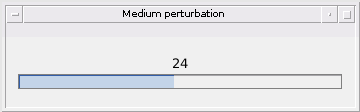

wtbr = waitbar(0, '0', 'Name', 'Medium perturbation'); 
for mediumPerturbation = 1:2
    if mediumPerturbation == 1
        uptakeRate = 10; 
    else 
        uptakeRate = 0.01;
    end 
    
    for i = 1:length(mediareactions1)
        finalUptakeRate = uptakeRate;
        if (mediumPerturbation == 2) & (ismember(i, [2, 3, 5:19])) % Trace elements
            finalUptakeRate = uptakeRate / 100;
        elseif (mediumPerturbation == 1) & (ismember(i, [1, 4]))   % Glucose or Glutamine
            finalUptakeRate = 3;
        end
        
        grateModel         = acetylation_model;
        [ix, pos]          = ismember(mediareactions1(i), grateModel.rxns);
        grateModel.lb(pos) = -media_exchange1(i, 1) * finalUptakeRate;
        
        % Compute growth rate
        [solf.x, ~] =  constrain_flux_regulation(grateModel, ...
                                                 [], [], ...
                                                 0, 0, 0, ...
                                                 [], [], ...
                                                 false);
        
        str = ['grate_', num2str(mediumPerturbation), '(i, 1) = solf.x(objpos);'];
        if ~isempty(solf.x) & ~isnan(solf.x)
            eval(str)
        end
        
        acetylationModel                  = grateModel;
        acetylationModel.c(histoneRxnPos) = acetylationCoefficient;
        
        % Compute histone flux 
        [solf.x, ~] =  constrain_flux_regulation(acetylationModel, ...
                                                 [], [], ...
                                                 0, 0, 0, ...
                                                 [], [], ...
                                                 false);
        str = ['acetylation_', num2str(mediumPerturbation), '(i, 1) = solf.x(histoneRxnPos);'];
        if ~isempty(solf.x) & ~isnan(solf.x)
            eval(str)
        end
        waitbar(i/length(mediareactions1), wtbr, sprintf('%d', i))
    end
end

## Plot a barplot of the histone acetylation fluxes

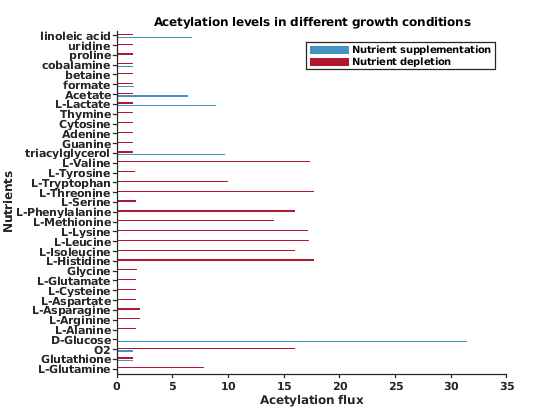

labels(2) = {'Glutathione'};
idx = [1:4, 20:50];

figure;
h = barh([acetylation_1(idx), acetylation_2(idx)],...
    'edgecolor', 'w');
h(1).FaceColor = '#4393c3';
h(2).FaceColor = '#b2182b';
title('Acetylation levels in different growth conditions', ...
      'fontweight', 'bold')
set(gca,'ytick', ...
    [1:length(mediareactions1(idx))], ...
    'yticklabel', labels(idx), ...
    'fontsize', 8, ...
    'fontweight', 'bold', ...
    'TickDir', 'out', ...
    'box', 'off', ...
    'linewidth', 1, ...
    'color', 'white');
xlabel('Acetylation flux'); ylabel('Nutrients');
legend({'Nutrient supplementation', 'Nutrient depletion'});